# Figure 4: S_EE and S_II

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];
Panel2 = length(S_EEtest); Panel1 = length(S_IItest);
S_ElgnInd = 2; % NEED TO CHANGE TO 2!
S_IlgnInd = 2; % $(seq 2 4)
rI_L6Ind = 2;  % 3 6

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

Fig1 = figure('Name','SEE_SII','units','normalized','outerposition',[0 0 .80 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .015],[.08 .08],[.1 .1]);

for S_EEInd = 1:length(S_EEtest)
    S_EE = S_EEtest(S_EEInd);
    S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
    S_Elgn=S_Elgntest(S_ElgnInd);
    for S_IIInd = 1:length(S_IItest)
        S_II = S_IItest(S_IIInd);
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
        
        CurrentPanelFile = sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end

        % First axis for fr
        axes(ha(S_EEInd+Panel2*(S_IIInd-1)));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrEShow = CurrentFrE;
        CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrEShow(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        % set ticks, labels, titles, etc for axis1.

        if S_EEInd == 1
            ax = gca;
            ax.YAxis.FontSize = 13;
            ylabel({sprintf('S^{II}=%.3f',S_II),'','S^{EI}/S^{EE}'},'FontSize',16)

        else
            set(gca,'yticklabel','')
        end
                
        if S_IIInd == length(S_IItest)
            ax = gca;
            ax.XAxis.FontSize = 13;            
            xlabel('S^{IE}/S^{II}','FontSize',16);
        else
            set(gca,'xticklabel','')
        end
        axis square
        axis tight
        
        if S_IIInd == 1
            title({sprintf('S^{EE}=%.3f',S_EE),''},'FontSize',16) 
        end
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        hold on
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
        GreyHem = 0.5*ones(size(CurrentFrE));
        if NoFailWeight<0.11 || SIEWeight<1 % if impossible pattern show up on the left...
            FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
            
            
            
        end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        
        % Midpoint of Good Area
        CurrentFrEGA = CurrentFrE;
        CurrentFrEGA(CurrentFrE<=3 | CurrentFrE>=5 | ...
            CurrentFrI./CurrentFrE    <=3 | ...
            CurrentFrI./CurrentFrE    >=4.25) = nan;
        CurrentFrEGA(FailMap) = nan;
        GoodArea = (~isnan(CurrentFrEGA));
        
        GAratio = sum(double(GoodArea),'all')/(length(CurrentFrEGA(:)))
        if GAratio<0.007 % skip midpoint if too small
            disp('Good Area too small, Exit.')
        else
            [GA_SEIInd,GA_SIEInd,~] = find(GoodArea);
            MP_SEI = ContourData_7D.S_EItest(floor(mean(GA_SEIInd)))/S_EE;
            MP_SIE = ContourData_7D.S_IEtest(floor(mean(GA_SIEInd)))/S_II;
            scatter(MP_SIE,MP_SEI, 3000, 'k+','LineWidth',4)
        end
        
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        axis([min(ContourData_7D.S_IEtest/S_II) max(ContourData_7D.S_IEtest/S_II) ...
              min(ContourData_7D.S_EItest/S_EE) max(ContourData_7D.S_EItest/S_EE)])
        
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        
        sprintf('id1 = %.2f, id2 = %.2f, Fail = %.2f, SIEWgt = %.2f',...
                S_EE,S_II,NoFailWeight,SIEWeight)
        
            if S_EEInd == length(S_EEtest)
                if S_IIInd == 1
                    Pos1 = get(gca,'Position');
                elseif S_IIInd == length(S_IItest)
                    Pos2 = get(gca,'Position');
                end
            end
            
    end
end

GAratio = 1.5625e-04

Good Area too small, Exit.


ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.59, SIEWgt = 1.24'

GAratio = 2.3438e-04

Good Area too small, Exit.


ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.77, SIEWgt = 1.14'

GAratio = 0

Good Area too small, Exit.


ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.80, SIEWgt = 1.12'

GAratio = 0

Good Area too small, Exit.


ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.82, SIEWgt = 1.11'

GAratio = 0.0091

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.49, SIEWgt = 1.25'

GAratio = 0.0091

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.73, SIEWgt = 1.14'

GAratio = 0.0086

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.77, SIEWgt = 1.14'

GAratio = 0.0087

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.79, SIEWgt = 1.14'

GAratio = 0.0111

ans = 'id1 = 0.02, id2 = 0.08, Fail = 0.37, SIEWgt = 1.31'

GAratio = 0.0152

ans = 'id1 = 0.02, id2 = 0.12, Fail = 0.69, SIEWgt = 1.14'

GAratio = 0.0153

ans = 'id1 = 0.02, id2 = 0.16, Fail = 0.74, SIEWgt = 1.15'

GAratio = 0.0158

ans = 'id1 = 0.02, id2 = 0.20, Fail = 0.76, SIEWgt = 1.15'

GAratio = 0.0071

ans = 'id1 = 0.03, id2 = 0.08, Fail = 0.26, SIEWgt = 1.40'

GAratio = 0.0182

ans = 'id1 = 0.03, id2 = 0.12, Fail = 0.63, SIEWgt = 1.14'

GAratio = 0.0196

ans = 'id1 = 0.03, id2 = 0.16, Fail = 0.74, SIEWgt = 1.16'

GAratio = 0.0207

ans = 'id1 = 0.03, id2 = 0.20, Fail = 0.77, SIEWgt = 1.15'

GAratio = 0.0021

Good Area too small, Exit.


ans = 'id1 = 0.03, id2 = 0.08, Fail = 0.18, SIEWgt = 1.49'

GAratio = 0.0186

ans = 'id1 = 0.03, id2 = 0.12, Fail = 0.53, SIEWgt = 1.19'

GAratio = 0.0230

ans = 'id1 = 0.03, id2 = 0.16, Fail = 0.72, SIEWgt = 1.16'

GAratio = 0.0243

ans = 'id1 = 0.03, id2 = 0.20, Fail = 0.77, SIEWgt = 1.15'


cbr = colorbar(ax1a, 'Position', [Pos2(1)+Pos2(3)+0.02  Pos2(2)  0.03  Pos1(2)+Pos1(4)-Pos2(2)]);
caxis([0 15])
set(cbr,'YTick',0:15,'FontSize',13)

Save figures

FigurePaperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'Figure4';
savefig(Fig1,[FigurePaperpath FigName1 '.fig']);


Print Figs

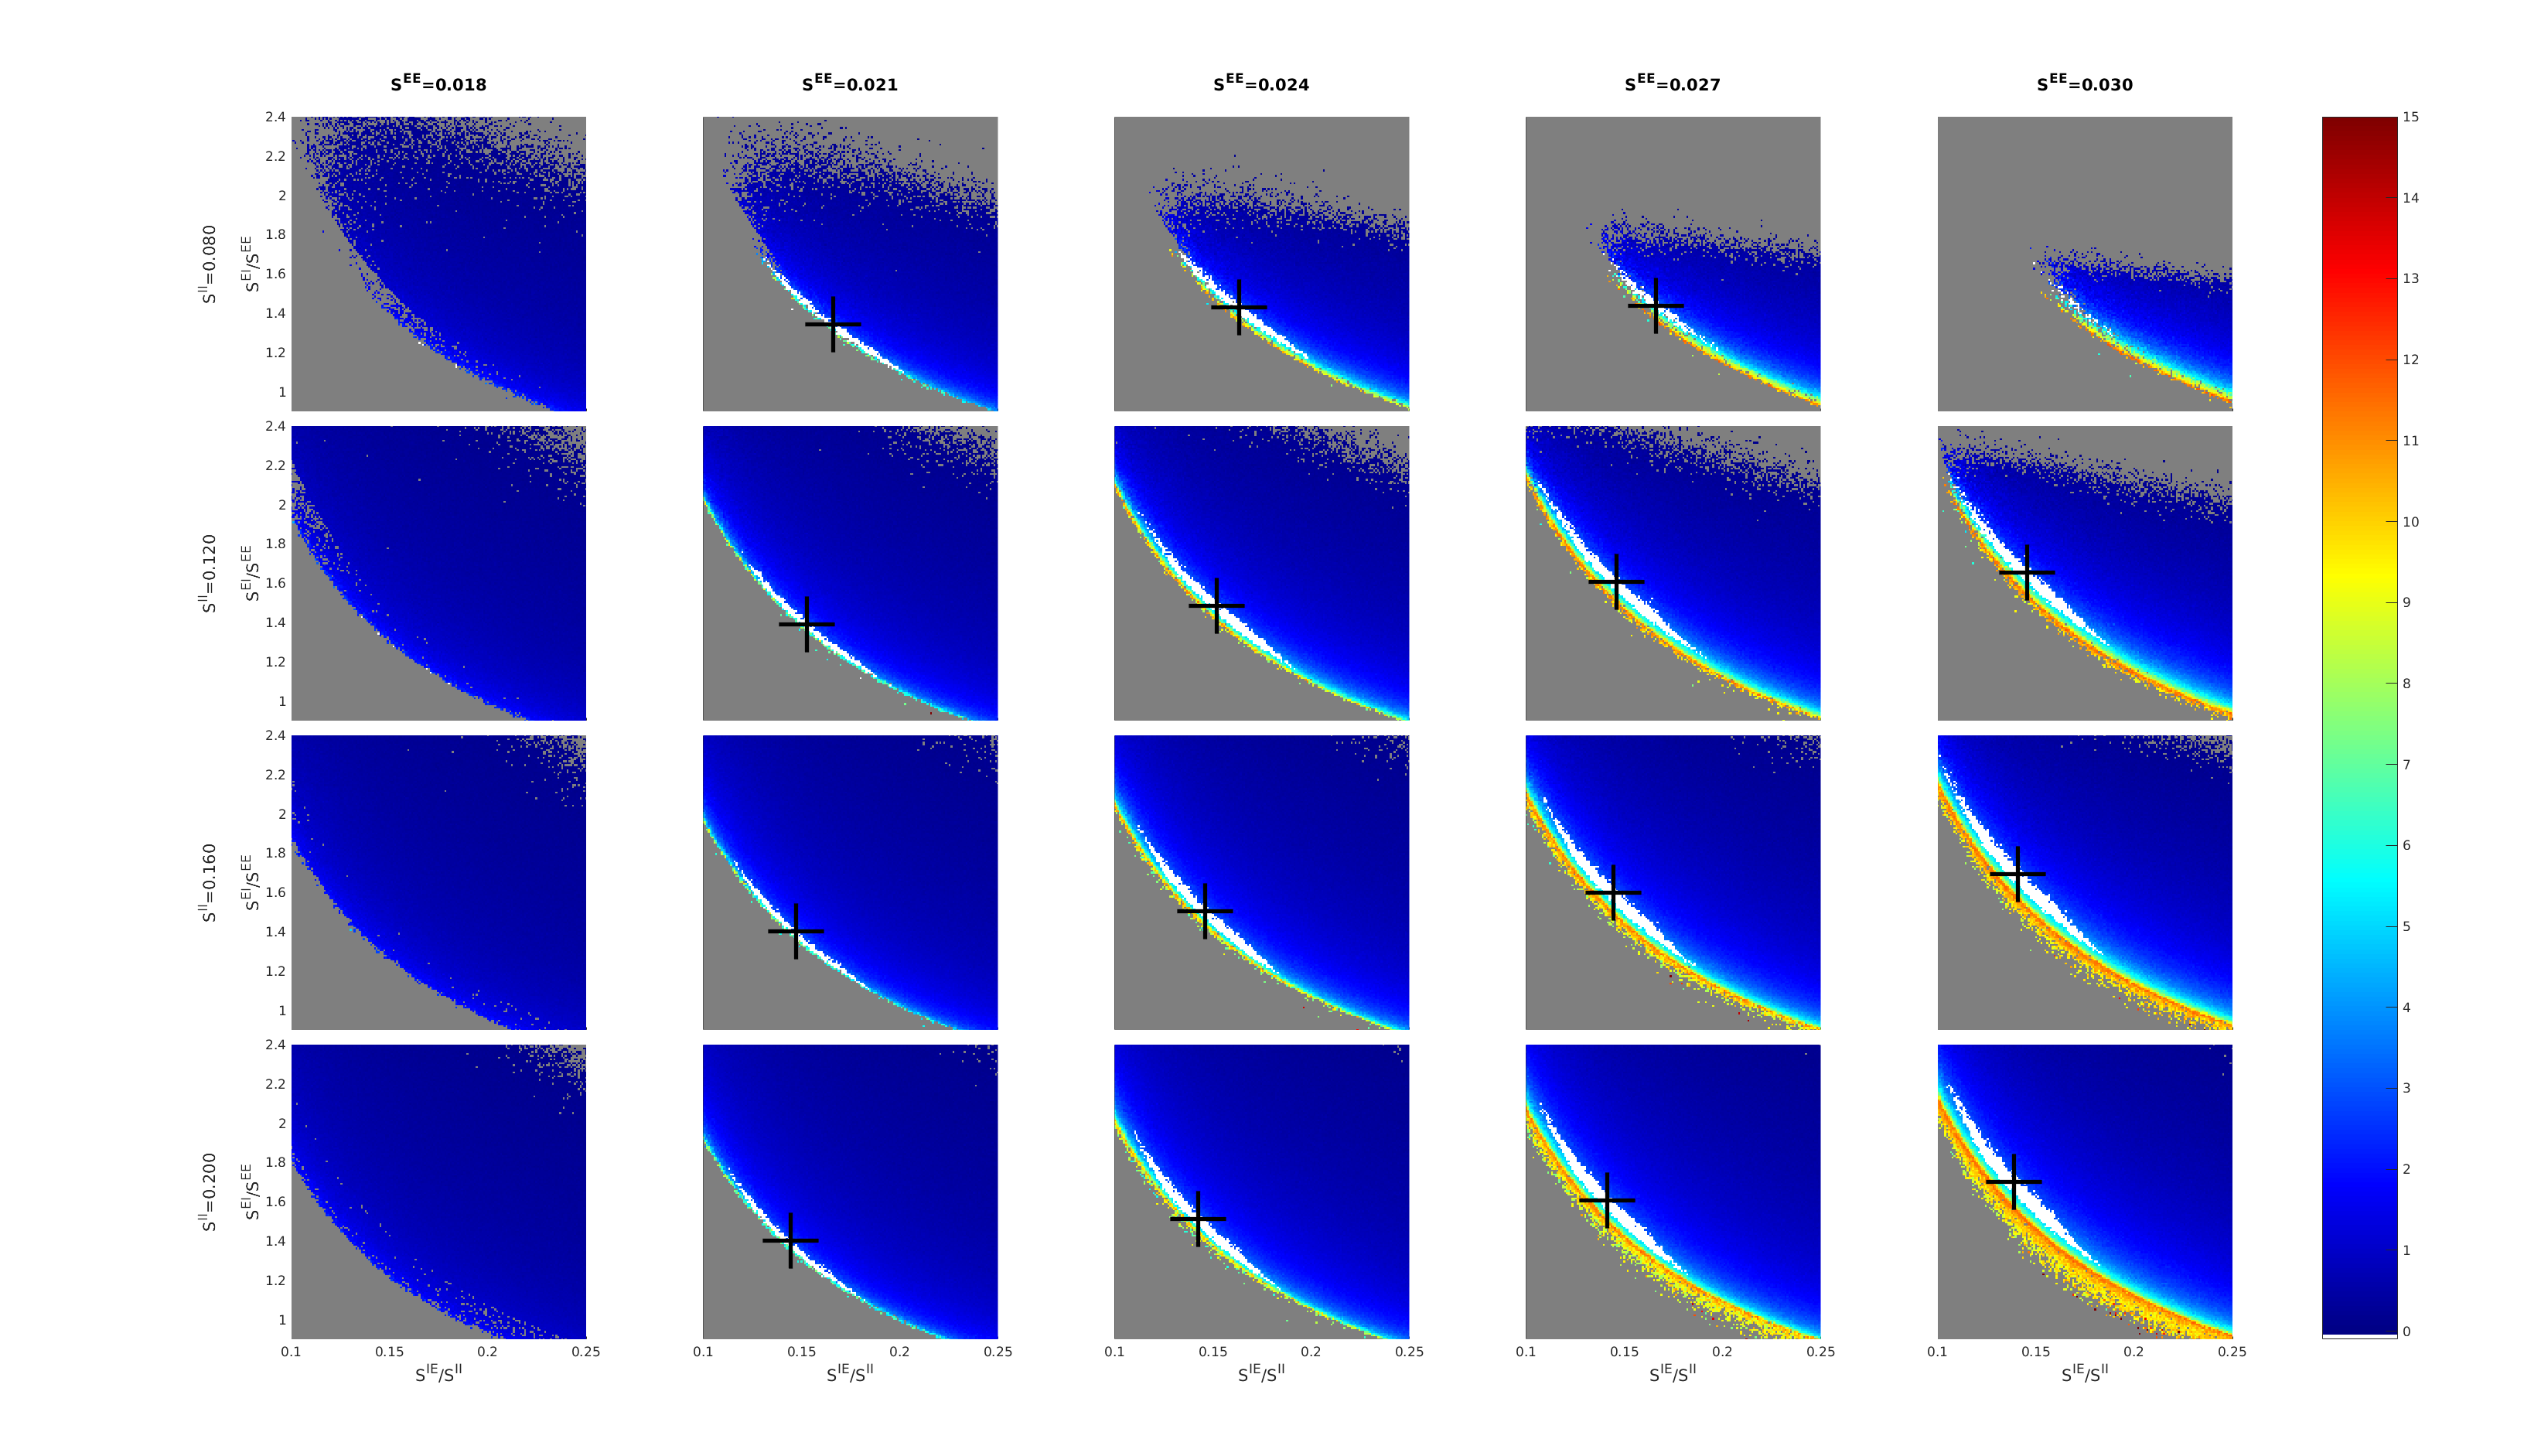

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [40,28];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[FigurePaperpath FigName1 '.pdf'],'Resolution',600)